%%%MLC_level1_Error分类
warning off  
clc
close all
clear
%读入数据
data=tabularTextDatastore("E:\Matlab_Code\MLC-dosimics\Level\Body_Clinical_Level1.csv");
ori_data=data.readall;
ori_data=ori_data(:,1:108);
predictors=ori_data.Properties.VariableNames;  %获取变量名特征
predictors(1)=[]; %去除其中的标签项目label  实际是应该为预测值
%predictors=predictors(:,8);

%数据按8:2分成测试集和验证集
C=cvpartition(ori_data.Label,'holdout',0.20);  
dataTrain = ori_data(C.training,:);  %只能用训练集 不能看测试集
dataTest = ori_data(C.test,:);
m=categorical(ori_data.Label);
label_class=categories(m);
class_num=numel(label_class);  %%用于XGboost分类数目输入
summary(m)  %展示每个分类的数量  用于后期XGboost输入分类数目

     Body            318 
     Error-free      318 
     Gantry          424 
     MLC-random      318 
     MLC-sys         424 
     MU              424 
     Set-up          636 


%%%使用相关性测试  去除高相关性  
%输入训练数据和相关性删除阈值0-1 输出为需要删除的特征、相关性矩阵和特征重要性
[feature_to_delete,corr_matrix,imp]=correlate_feature(dataTrain,0.8);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 16 workers.
最优参数为
    MinLeafSize    MaxNumSplits    SplitCriterion
    ___________    ____________    ______________

         1             2278             gdi      



%%展示相关性热图 

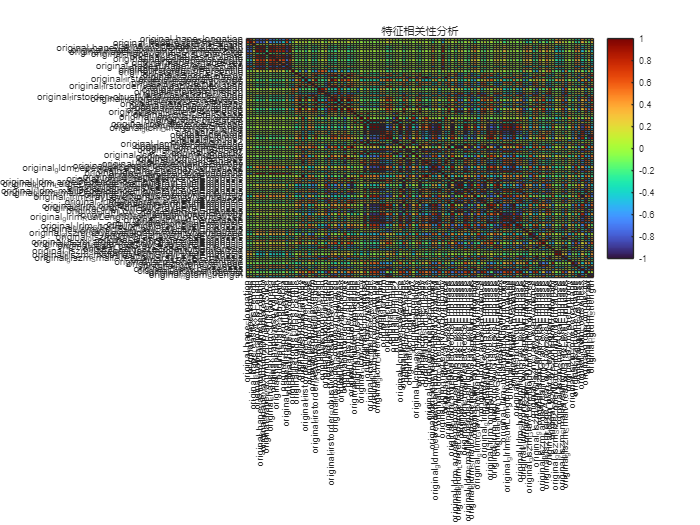

figure;a=heatmap(predictors, predictors, corr_matrix,...
    'Colormap', turbo, 'ColorLimits',[-1 1],...
    'Title','特征相关性分析', 'CellLabelFormat','%.2f');
a.FontSize=6; %设置字体大小

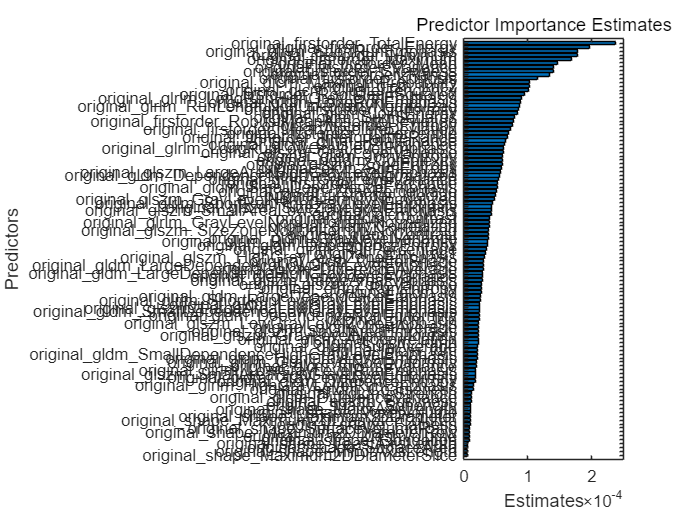

%%特征重要性排序
[sortedImportance, indices] = sort(imp, 'ascend');  %升序排列
%sortedNames=MLCtree_bag.PredictorNames(indices);
figure,bar(sortedImportance);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XAxisLocation='origin';
h.XTick=1:1:107;
h.XTickLabel = predictors(indices);
%h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';
view(90,-90);

%%筛除高相关性的特征  根据之前的结果选择剩余的特征feature_to_delete，使用递归法继续特征筛选
feature_delete_size=size(feature_to_delete);  %需要筛除特征的数量  删除79个左右
select_index=ismember(predictors,feature_to_delete);% 返回predictors中是否包含feature_to_delete的逻辑回复
FeatureByCorr=predictors(~select_index);%反逻辑索引得到筛选后的特征  剩余28个特征

%随机森林递归法进行特征筛选 
%输入训练数据  相关性筛选后的特征，输出5折交叉验证的精准度和auc
[Finalfeature,accuracy,auc_micro,auc_macro]=FeatureToRecursion(dataTrain,FeatureByCorr);

%画图递归AUC和accuracy的变化趋势
micro_flip=flip(auc_micro);
macro_flip=flip(auc_macro);
accuracy_flip=flip(accuracy);
x=1:1:size(macro_flip);

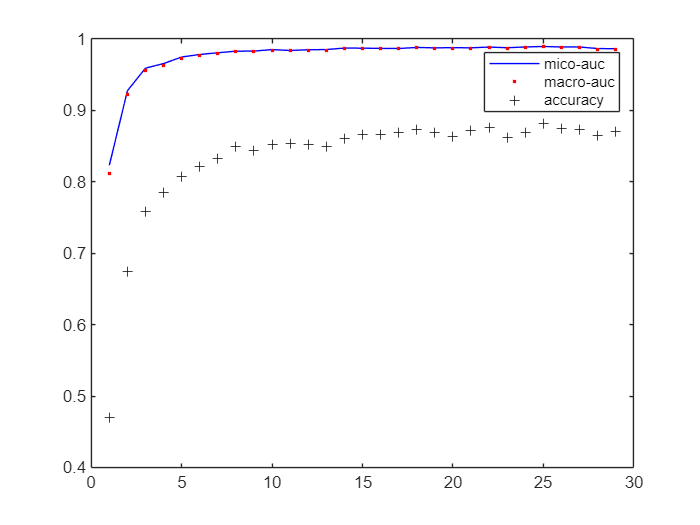


figure(11),plot(x,micro_flip,'b',x,macro_flip,'r.',x,accuracy_flip,'k+');
legend("mico-auc","macro-auc","accuracy","southeast")

选取最终的20个特征

final_predictors=Finalfeature(end-19:end,:);  %多维数组 选择末尾的20个特征
final_predictors=final_predictors';%转换为列向量
selected_feature = cellfun(@(x) x{:},final_predictors, 'UniformOutput', false); %去掉内置的cell单元格 以便后续fitcensemble输出

使用随机森林算法进行分类

[RFmodel,impreditors]=RandomForest(dataTrain,selected_feature);

正在使用 'Processes' 配置文件启动并行池(parpool)...


%%特征重要性排序
[sortedImpreditors, imp_index] = sort(impreditors, 'ascend');  %升序排列
%sortedNames=MLCtree_bag.PredictorNames(indices);
feature_len=size(sortedImpreditors,2);%获取最终特征长度

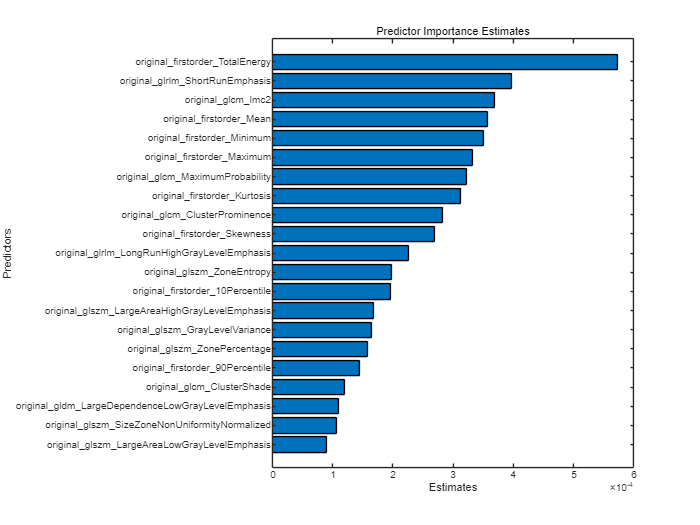

figure,bar(sortedImpreditors);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XAxisLocation='origin';
h.XTick=1:1:feature_len;
h.XTickLabel = selected_feature(imp_index);
%h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';
view(90,-90);
h.FontSize=6;

训练集五折交叉验证准确率 85.76 %.
训练集五折交叉验证精确率 0.8573.
训练集五折交叉验证召回率 0.8512.
训练集五折交叉验证F1分数 0.8533.
独立测试集准确率 88.11 %.
独立测试集精确率 0.8825.
独立测试集召回率 0.8791.
独立测试集F1分数 0.8806.


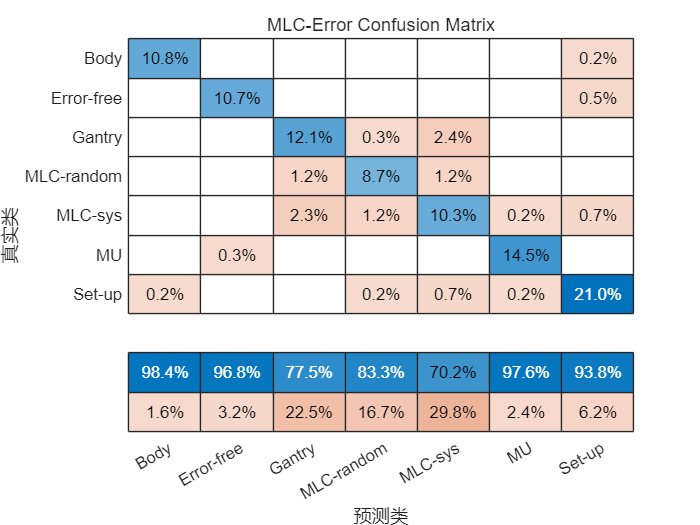

%%%进行模型评估  输出训练集的准确率 测试集的准确率
[Metrics_CV_RF, Metrics_Test_RF]=eval_model(RFmodel,dataTrain,dataTest);

XGBoost分类算法测试

训练集五折交叉验证准确率 88.30 %.
训练集五折交叉验证精确率 0.8833.
训练集五折交叉验证召回率 0.8795.
训练集五折交叉验证F1分数 0.8801.
独立测试集准确率 90.21 %.
独立测试集精确率 0.9019.
独立测试集召回率 0.9049.
独立测试集F1分数 0.9031.


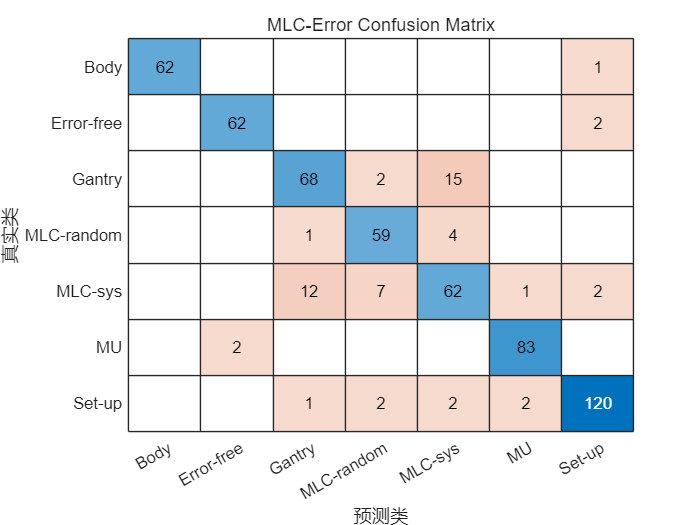

haha

[metrics_cv_XG,metrics_test_XG,XGmodels,XGclassNames,cm_xg]=XGBoost(dataTrain,dataTest,selected_feature,class_num);

支持向量机多分类算法

svm_model=SVM(dataTrain,selected_feature);

=== 支持向量机最优超参数 ===
     Coding     BoxConstraint    KernelScale    KernelFunction    PolynomialOrder    Standardize
    ________    _____________    ___________    ______________    _______________    ___________

    onevsone       990.33           3.238          gaussian             NaN             true    



训练集五折交叉验证准确率 86.55 %.
训练集五折交叉验证精确率 0.8688.
训练集五折交叉验证召回率 0.8644.
训练集五折交叉验证F1分数 0.8658.
独立测试集准确率 81.64 %.
独立测试集精确率 0.8255.
独立测试集召回率 0.8138.
独立测试集F1分数 0.8167.


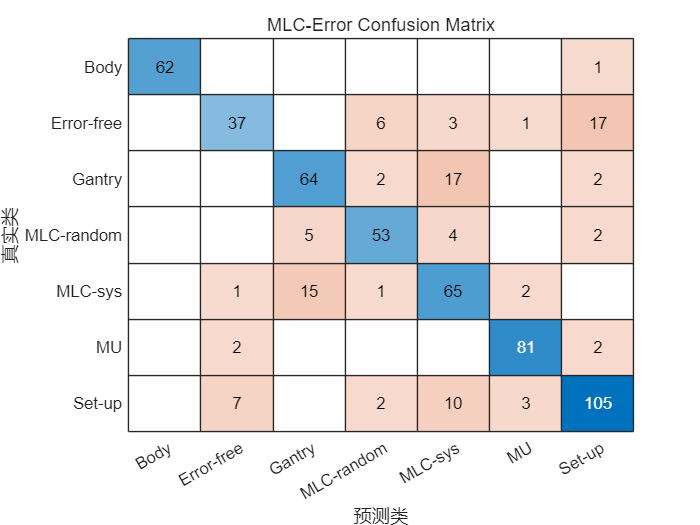

%%%进行模型评估  输出训练集的准确率 测试集的准确率
[metrics_cv_svm,metrics_test_svm,cm_svm] = eval_model(svm_model,dataTrain,dataTest);

神经网络分类算法

nn_model=NeuralNet(dataTrain,selected_feature);

=== 支持向量机最优超参数 ===
    NumLayers    Activations    Standardize      Lambda      Layer_1_Size    Layer_2_Size    Layer_3_Size
    _________    ___________    ___________    __________    ____________    ____________    ____________

        1           relu           true        2.8502e-05        289             NaN             NaN     



训练集五折交叉验证准确率 87.21 %.
训练集五折交叉验证精确率 0.8748.
训练集五折交叉验证召回率 0.8690.
训练集五折交叉验证F1分数 0.8712.
独立测试集准确率 88.64 %.
独立测试集精确率 0.8935.
独立测试集召回率 0.8860.
独立测试集F1分数 0.8893.


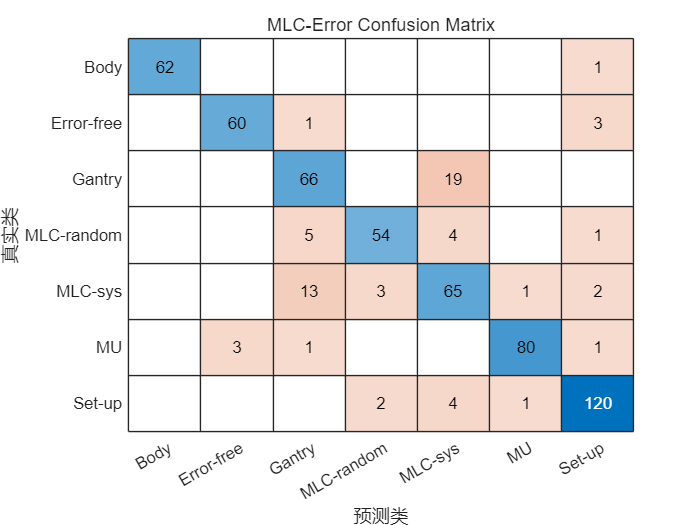

%%%进行模型评估  输出训练集的准确率 测试集的准确率
[metrics_cv_NN, metrics_test_NN] = eval_model(nn_model,dataTrain,dataTest);

临床测试

%读入数据
ClinicalDataTable = tabularTextDatastore("E:\Matlab_Code\MLC-dosimics\Level\Body_ClinicalTest_Level1.csv");

Clinical_data = ClinicalDataTable.readall;
CTest_data = Clinical_data(:,1:108);
predictors = CTest_data.Properties.VariableNames;  %获取变量名特征
predictors(1)=[]; %去除其中的标签项目label  实际是应该为预测值
%predictors=predictors(:,8);

%添加高斯噪声
CTest_data = AddNoise(CTest_data);

噪声添加完毕

%噪声处理完毕

classnum = categorical(CTest_data.Label);
summary(classnum)  %展示每个分类的数量  用于后期XGboost输入分类数目

     Body             60 
     Error-free       60 
     Gantry           80 
     MLC-random       60 
     MLC-sys          80 
     MU               80 
     Set-up          120 


临床测试集准确率 72.96 %.
临床测试集精确率 0.7688.
临床测试集召回率 0.7238.
临床测试集F1分数 0.7309.


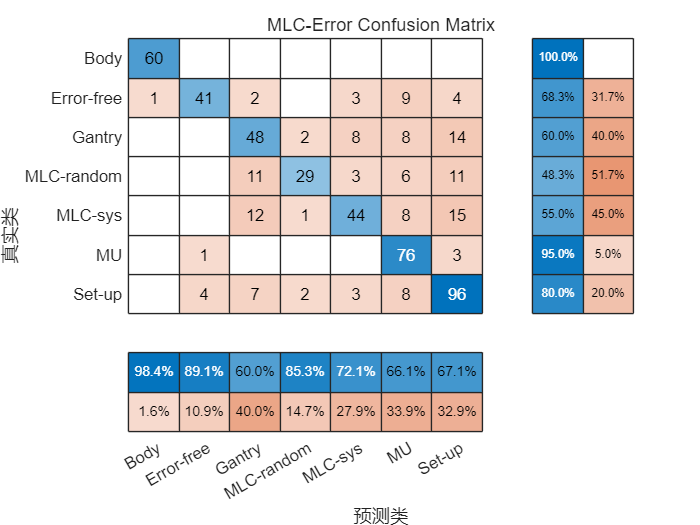

[Metrics_clinic_test_NN, score_NN, className_NN] =Clinicaleval_model(nn_model, CTest_data);

临床测试集准确率 62.59 %.
临床测试集精确率 0.6598.
临床测试集召回率 0.6369.
临床测试集F1分数 0.6270.


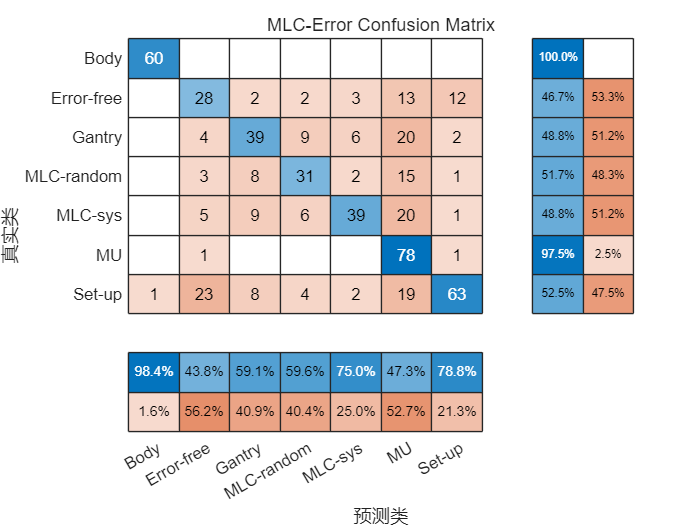

[clinic_test_svm, score_svm, className_svm] =Clinicaleval_model(svm_model, CTest_data);

临床测试集准确率 74.81 %.
临床测试集精确率 0.8260.
临床测试集召回率 0.7423.
临床测试集F1分数 0.7469.


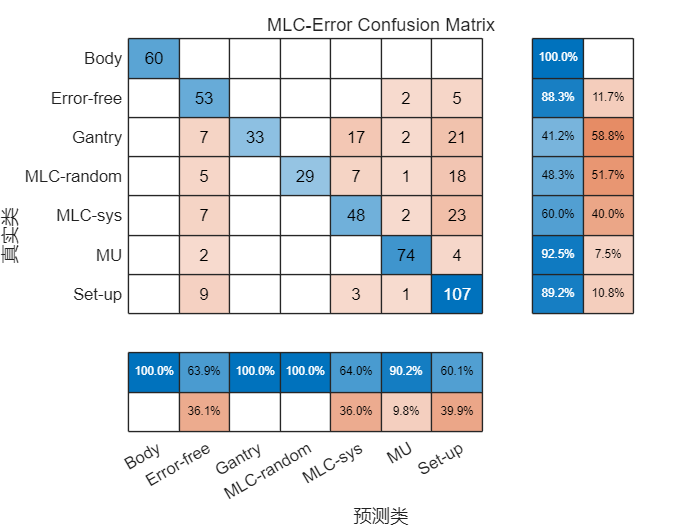

[XGscores,Metrics_clinic_test_XG] = XGBoost_eval_model(XGmodels,selected_feature, CTest_data,XGclassNames);

Micro-average AUC: 0.9629
Micro-average AUC: 0.9901
Micro-average AUC: 0.9909


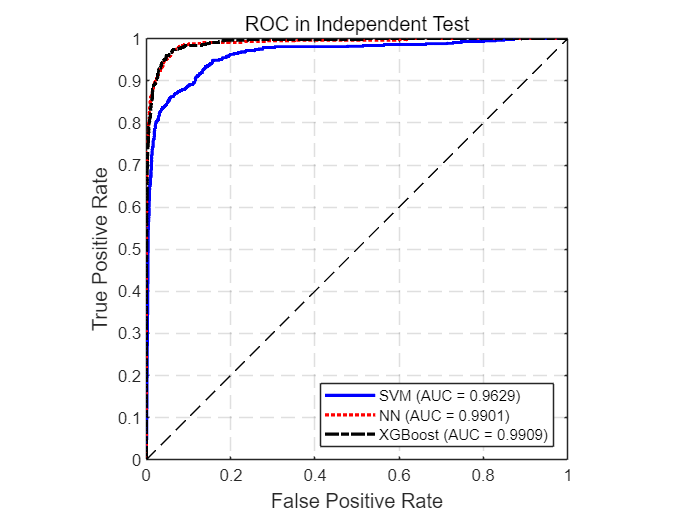

figure(9),plot_roc_curve(dataTest, svm_model, nn_model, XGmodels,XGclassNames,selected_feature,'ROC in Independent Test');

figure(10),plot_roc_curve(CTest_data, svm_model, nn_model, XGmodels,XGclassNames,selected_feature,'ROC in Clinical Test');


## 加载机器学习和深度学习测试结果

load("BodyClinicalLevel1.mat");

load("DeepData.mat");
DP_TestLabels = Data_Test.Labels;         %获取深度学习测试集标签
DP_CTestLabels = Data_clinic_Test.Labels; %获取深度学习临床测试集标签

%% 画图测试集结果
figure(11), plot_roc_curve4(dataTest, svm_model, nn_model, XGmodels,XGclassNames,selected_feature,...
    Pred_DP_Test,Score_DP_Test,DP_TestLabels,'Independent Test for Level-1');

函数或变量 'Pred_DP_Test' 无法识别。

%%% 画图临床测试集对比结果
figure(12), plot_roc_curve4(CTest_data, svm_model, nn_model, XGmodels,XGclassNames,selected_feature,...
    Pred_DP_CTest,Score_DP_CTest,DP_CTestLabels,'Clinical Test for Level-1');

函数或变量 'Pred_DP_CTest' 无法识别。